clear
clc
close all

## Determine Hyper Parameters

totalwidth = 840 * 0.78 * 1; %%%%%%%%%%%%%%
totalheight = 900 * 0.98;
figure('Position',[0,0,totalwidth,totalheight])
% set(gcf,'units','centimeters','position',[0,0,174,174/1.2375])
set(gcf,'Color','white')


timespan = 60;
timebeginuntil = 0;

ymin = 0;
ymax = 1;
xmax = timespan;
top = 0.99;
% width = 240/totalwidth;
width = 320/(825 * 1.5) * 3.2 * 1; %%%%%%%%%%%%%%
height = 20/totalheight;
topshift = 1.65*height;
bigtopshift = 4.25*height;
% leftshift = 4/3*width;
leftshift = 0.75*width;
% delta = 0.1*0.6/1.1;
delta = 0.1*0.7/1.5;
delta = delta/(width-delta);

sensorycolorset = [[83,236,141]/255;...
    [95,107,223]/255;...
    [80,203,242]/255];

neuroncolorset = [[0,0,0]/255;...
    [217,75,73]/255;...
    [85,126,188]/255;...
    [190,96,181]/255;...
    [124,124,124]/255;...
    [84,130,53]/255;...
    [210,151,191]/255;...
    [88 152 196]/255;
    [255 217 102]/255;
    [54 166 185]/255];

kimkincolorset = ['b';'k'];

sensoryset = {'sens_mechanical_grasper','Mech. in Grasper',1,[0,1];...
    'sens_chemical_lips','Chem. at Lips',2,[0,1];...
    'sens_mechanical_lips','Mech. at Lips',3,[0,1]};

neuronset = {'f_CBI2','CBI2',1;...
    'f_CBI3','CBI3',1;...
    'f_CBI4','CBI4',1;...
    'f_B63','B63',2;...
    'f_B64','B64',3;...
    'f_B52','B52',3;...
    'f_B34','B34',4;...
    'f_B40','B40',4;...
    'f_B65','B65',5;...
    'f_B30','B30',5;...
    'f_B20','B20',6;...
    'f_B45','B4',6;...
    'f_B31','B31',2;...
    'f_B69','B6',8;...
    'f_B8','B8',7;...
    'f_B38','B38',9;...
    'f_B7','B7',10};
for k = 1:length(neuronset)
    neuronset{k,4} = [0,1];
end

kimkinset = {'xgh',{'Grasper','Motion'},1,[0,1];...
    'force','Force',2,[-0.5,0.5]};

titleset = {'(\bfA\rm) Biting','(\bfB\rm) Swallowing','(\bfC\rm) Rejection'};

plotparam = [top,width,height,topshift,bigtopshift,xmax,delta];

## Initialization

ModularAplysia_1282022_withSNS_initialization;
MechanicsParaOriginal;
InitPara;
CtrlParaSNSTuning;
seaweed_strength = 10;
mu_s_g = 0.45;
mu_k_g = 0.3;
mu_s_h = 0.3;
mu_k_h = 0.3;
max_I3ant = 1.2;

## Simulation

endTime = 80;
simout = sim('ModularAplysia_1282022_biting2swallowing.slx', 'StopTime',string(endTime),'MinStep','0.001');

## Plotting

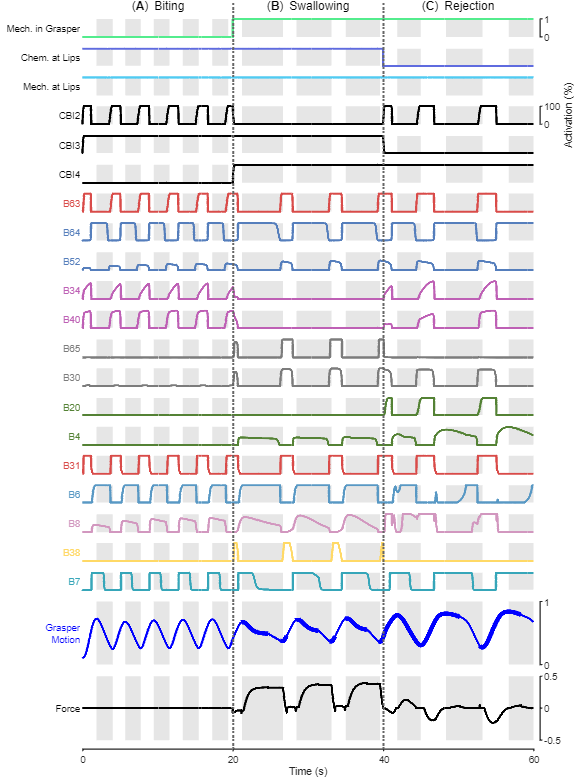

colindex = 1;
vth = -1e-6;
index = patternplot(simout,timespan,timebeginuntil,plotparam,neuronset,kimkinset,sensoryset,neuroncolorset,kimkincolorset,sensorycolorset,titleset,colindex,vth);

## Local Functions

function index = patternplot(simout,timespan,timebeginuntil,plotparam,neuronset,kimkinset,sensoryset,neuroncolorset,kimkincolorset,sensorycolorset,titleset,colindex,vth)
    [protractionRectangles,index] = prorec(simout,timespan,timebeginuntil,vth);
    for k = 1:size(neuronset,1) + size(kimkinset,1) + size(sensoryset,1) 
        topnow = kimkinneusubplot(simout,k,colindex,neuronset,kimkinset,sensoryset,neuroncolorset,kimkincolorset,sensorycolorset,protractionRectangles,index,plotparam);
        if k == 1
            xmax = plotparam(end-1);
            text(xmax/6,1.2,titleset{1},'FontSize',10,'VerticalAlignment','bottom','HorizontalAlignment','center');
            text(xmax/6*3,1.2,titleset{2},'FontSize',10,'VerticalAlignment','bottom','HorizontalAlignment','center');
            text(xmax/6*5,1.2,titleset{3},'FontSize',10,'VerticalAlignment','bottom','HorizontalAlignment','center');
        elseif k == size(neuronset,1) + size(kimkinset,1) + size(sensoryset,1) && colindex == 1
            xaxisplot(0,plotparam,topnow)
        end
    end
end

function [protractionRectangles,index] = prorec(simout,timespan,timebeginuntil,vth)
    startnum = 0;
    endnum = length(simout.tout);
    grasper_rel_pos = simout.xgh;
    numProtractionBoxes = 0;
    numRetractionBoxes = 0;
    protraction = 0;
    protractionRectangles=[0,0];
    retractionRectangles=[0,0];
    for ind=startnum+2:endnum
        if (grasper_rel_pos(ind) - grasper_rel_pos(ind-1))/(simout.tout(ind) - simout.tout(ind-1)) > -vth
            %protraction
            if(protraction == 0)
                numProtractionBoxes=numProtractionBoxes+1;
                protraction = 1;
                %end the last retractionrectangle
                if(numRetractionBoxes>0)
                    retractionRectangles(numRetractionBoxes,2) = ind;
                end
                %start a new protractionrectangle
                protractionRectangles(numProtractionBoxes,1) = ind;
            end
        else
            %retraction
            if(protraction == 1)
                numRetractionBoxes=numRetractionBoxes+1;
                protraction = 0;
                %end the last retractionrectangle
                retractionRectangles(numRetractionBoxes,1) = ind;
                %start a new protractionrectangle
                if(numProtractionBoxes>0)
                    protractionRectangles(numProtractionBoxes,2) = ind;
                end
            end
        end
    end
    
    if protractionRectangles(end,2) == 0
        protractionRectangles(end,2) = endnum;
    end
    
    k = 2;
    while 1
        if k > size(protractionRectangles,1)
            break;
        elseif simout.tout(protractionRectangles(k,1)) - simout.tout(protractionRectangles(k-1,2)) < 1.5
            protractionRectangles(k-1,2) = protractionRectangles(k,2);
            protractionRectangles(k,:) = [];
            continue;
        end
        k = k + 1;
    end

    k = 1;
    while 1
        if k > size(protractionRectangles,1)
            break;
        elseif simout.tout(protractionRectangles(k,2)) - simout.tout(protractionRectangles(k,1)) < 1
            protractionRectangles(k,:) = [];
            continue;
        end
        k = k + 1;
    end   

    protractionRectangles = protractionRectangles(simout.tout(protractionRectangles(:,1)) > timebeginuntil,:);
    
    % beginindex = protractionRectangles(1,1);
    beginindex = 1;
    endindex = find(simout.tout >= simout.tout(beginindex) + timespan,1,'first');
    index = beginindex:endindex;
end

function topnow = kimkinneusubplot(simout,i,colindex,neuronset,kimkinset,sensoryset,neuroncolorset,kimkincolorset,sensorycolorset,protractionRectangles,index,plotparam)
    top = plotparam(1);
    width = plotparam(2);
    height = plotparam(3);
    topshift = plotparam(4);
    bigtopshift = plotparam(5);
    xmax = plotparam(6);
    delta = plotparam(7);
    stateset = [sensoryset;neuronset;kimkinset];
    statename = stateset{i,1};
    label = stateset{i,2};
    modulenum = stateset{i,3};
    yrange = stateset{i,4};
    if i > size(neuronset,1) + size(sensoryset,1)
        color = kimkincolorset(modulenum,:);
        topnow = top - (size(neuronset,1) + size(sensoryset,1))*topshift - (i - size(neuronset,1) - size(sensoryset,1))*bigtopshift - 0*topshift;
        subplot('position',[0.13*width + (colindex-1)*width,topnow,width,3.6*height]); %%%%%%%%%%%%%%%%%%%%%%%% 0.12
    elseif i > size(sensoryset,1)
        color = neuroncolorset(modulenum,:);
        topnow = top - size(sensoryset,1)*topshift - (i - size(sensoryset,1))*topshift - 0*topshift;
        subplot('position',[0.13*width + (colindex-1)*width,topnow,width,height]);
    else
        color = sensorycolorset(modulenum,:);
        topnow = top - i*topshift;
        subplot('position',[0.13*width + (colindex-1)*width,topnow,width,height]);
    end
    % if i == 1
    prophaseplot(xmax,simout,protractionRectangles,yrange,[0.9,0.9,0.9]);
    % end
    t = simout.tout(index)-simout.tout(index(1));
    if size(simout.(statename),1) == 1
        y = simout.(statename) * ones(size(simout.tout));
    else
        y = simout.(statename);
    end
    if i ~= size(neuronset,1) + size(sensoryset,1) + size(kimkinset,1) - 1
        plot(t,y(index,end),'Color',color,'LineWidth',2);
    else
        grasper_motion = simout.x_g(index) - simout.x_h(index);
        grasper_pressure = simout.grasper_friction_state.Data(index);
        idy = grasper_pressure < 0.5;
        grasper_motion_pressure = grasper_motion;
        grasper_motion_pressure(idy) = NaN;
        plot(t,grasper_motion_pressure,'Color',color,'LineWidth',4)
        plot(t,grasper_motion,'Color',color,'LineWidth',2)
    end
    hold off
    if ((i == 1) || (i == 1 + size(sensoryset,1)) || (i > size(sensoryset,1) + size(neuronset,1))) && (colindex == 1)
        kimkinneuformat(i,colindex,xmax,yrange,delta,label,color,1);
    else
        kimkinneuformat(i,colindex,xmax,yrange,delta,label,color);
    end
    set(gca,'color','none','Clipping','off')
end

function kimkinneuformat(i,colindex,xmax,yrange,delta,label,color,varargin)
    xlim([-3 * delta / 4 * xmax,(1 + delta / 4) * xmax]);
    ylim(yrange);
    set(gca,'FontSize',8);
    set(gca,'xtick',[]);
    set(gca,'box','off');
    set(gca,'XColor','none');
    set(gca,'color','none','Clipping','off')
    if colindex == 1
%         text(-0.75*delta*xmax,mean(yrange),label,'Color',color)
        if i < 4
            text(-0.07*delta*xmax,mean(yrange),label,'Color','k','HorizontalAlignment','right','FontSize',8)
        else
            text(-0.07*delta*xmax,mean(yrange),label,'Color',color,'HorizontalAlignment','right','FontSize',8)
        end
        if nargin > 7
            if abs(yrange(1)) > 1e-4
                ytick = [yrange(1),mean(yrange),yrange(2)];
            else
                ytick = yrange;
            end
            if i == 1
                yticklabel = string(ytick);
            elseif i > 20
                yticklabel = string(ytick);
            else
                yticklabel = string(100*yrange);
                ylabel('Activation (%)');
            end
            set(gca,'ytick',ytick);
            set(gca,'YTickLabel',yticklabel);
            set(gca,'TickDir','out');
            set(gca,'LineWidth',1,'TickLength',[0.0034,0.0034],'YAxisLocation','right');
        else
            set(gca,'YColor','none');
        end
    else
        set(gca,'YColor','none');
    end
end

function prophaseplot(xmax,simout,protractionRectangles,yrange,color)
    % beginindex = protractionRectangles(1,1);
    beginindex = 1;
    for k = 1:length(protractionRectangles) - 1
        t = simout.tout(protractionRectangles(k,2):protractionRectangles(k + 1,1)) - simout.tout(beginindex);
        if t(1) < 60
            t = t(t < xmax);
            y = ones(size(t));
            fill([t;flipud(t)],[yrange(1)*y;flipud(yrange(2)*y)],color,'LineStyle','none')
            if k == 1
                hold on
            end
        end
    end
end

function xaxisplot(xmin,plotparam,topnow)
    top = plotparam(1);
    width = plotparam(2);
    height = plotparam(3);
    xmax = plotparam(6);
    delta = plotparam(7);
    subplot('Position',[0.13*width + 3/4*delta/(1+delta)*width,topnow - 0.25*delta*width/(1+delta),width/(1+delta),height*0.1])
    y = [0, 10 * (top - topnow) / height];
    for x = xmax / 3:xmax / 3:xmax / 3 * 2
        line(x * ones(size(y)), y,'LineStyle',':','LineWidth',1.75,'Color',[0.4,0.4,0.4])
    end

    xlim([xmin xmax]);
    ylim([0 1]);
    xticks(linspace(xmin,xmax,4))
    set(gca,'FontSize',8);
    set(gca,'TickDir','out');
    set(gca,'LineWidth',1,'TickLength',[0.0034,0.0034]);
    set(gca,'box','off');
    set(gca,'YColor','none');
    xlabel('Time (s)');
    set(gca,'color','none','Clipping','off')
end